# **Проектирование прёмной АФАР**

clear
Kpdb=17 %db

Kpdb = 17

Kp=db2pow(Kpdb)

Kp = 50.1187

Kndb=3.5 %db

Kndb = 3.5000

Kn=db2pow(Kndb)

Kn = 2.2387

p=4

p = 4

wavlen=8 %cm

wavlen = 8

scanang=22 %+-deg

scanang = 22

beamwidthx=2 %deg

beamwidthx = 2

beamwidthy=2 %deg

beamwidthy = 2

tmax=-17 %db УБЛ

tmax = -17


$$t\approx-(13+13\Delta+22\Delta^2)$$


откуда $\Delta=$

syms x;
delta=max(double(solve(-13-13*x-22*x^2==tmax)));
disp(vpa(delta,2))

$$0.22$$


$$f(\theta)=cos^a(\theta)$$



$$cos^{2\alpha}\theta^{\circ}_{\text{ск}}=1/2$$



$$\alpha=0.5\cdot\frac{log0.5}{log(cos(\theta^\circ))}=$$


alph=0.5*log(0.5)/log(cosd(scanang));
disp(vpa(alph,3))

$$4.58$$


$$cos^{2\alpha}\theta_\text{Д}=t$$


t=

disp(vpa(db2pow(tmax),2))

$$0.02$$


$$\theta_\text{Д}=arccos(\sqrt[2\alpha]{t_\text{ед}})=$$


thetadif=acosd(db2pow(tmax)^(1/(2*alph)));
disp(vpa(thetadif,4))

$$49.27$$


$$d\leq\frac{\lambda}{sin\theta_\text{Д}+sin\theta_\text{ск}}=$$


d=wavlen/(sind(thetadif)+sind(scanang));
disp(vpa(d,4))

$$7.065$$


$$N_1=\frac{(1+0.636\cdot\Delta^2)\cdot51^\circ\cdot\lambda}{\theta_{0.5x}\cdot d}=$$


N1=ceil((1+0.636*delta^2)*51*wavlen/(beamwidthx*d));
disp(N1)

    30




$$N_2=\frac{(1+0.636\cdot\Delta^2)\cdot51^\circ\cdot\lambda}{\theta_{0.5y}\cdot d}=$$


N2=ceil((1+0.636*delta^2)*51*wavlen/(beamwidthy*d));
disp(N2)

    30



Длина $L$ и ширина $W$ решетки равны

L=N1*d;
W=N2*d;
fprintf('L = %.1f см, W = %.1f см',L,W)

L = 211.9 см, W = 211.9 см

Общее число элементов $N=N^2_1=$

N=N1*N2;
disp(N)

   900



Рассмотрим одноэтажную схему. Для приёмного тракта на 

disp(N)

   900



элементов потребуется сумматор на 

NN=2^nextpow2(N);
disp(NN)

        1024



Неиспользуемые входы сумматора включим на согласованную нагрузку на уровнях(е)

nn=NN-N;
xb=dec2bin(nn);
ind=1;
for i=length(xb):-1:1
    if(str2num(xb(i)))
        level(ind)=length(xb)+1-i;
        ind=ind+1;
    end
end
disp(level)

     3     4     5     6     7



clear i ind xb level

____________________________________________

### Расчет энергетического потанцевала

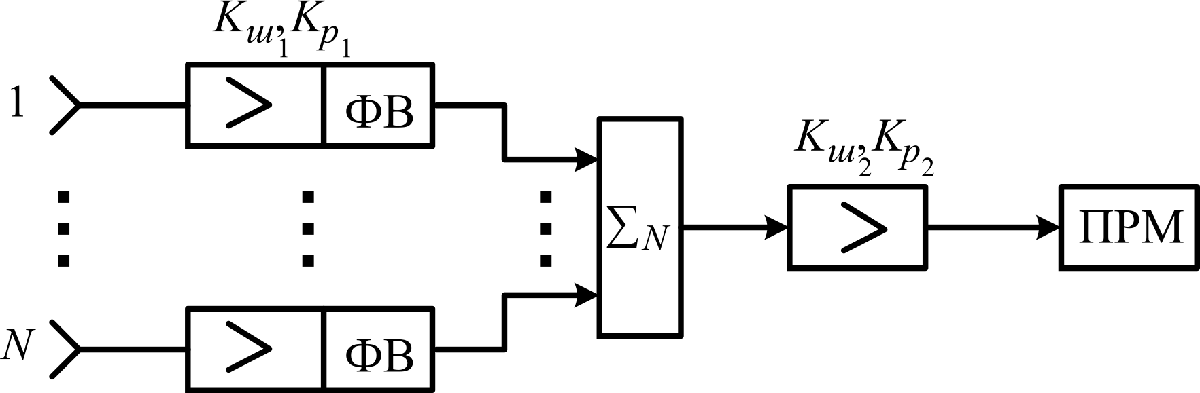

Схема прохождения по каналу:

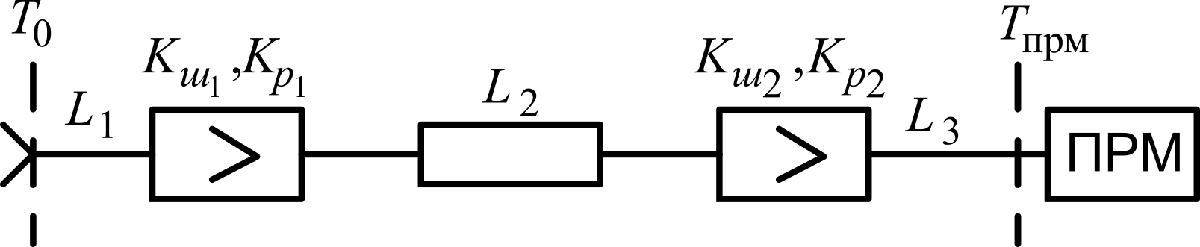

погонные потери в соединительных кабелях (излучателя с МШУ) $l_\text{каб}$ возьмём равными $1 \text{ дБ/м}$, тогда потери в кабелях $L_\text{каб}=l_\text{каб}\cdot\sqrt{L^2+W^2}/2=$

lcab=1;
Lcab=sqrt(L^2+W^2)/2*lcab/100;
fprintf('Lcab = %.1f дБ', Lcab)

Lcab = 1.5 дБ

Возьмём потери в кабеле и фильтре МШУ $L_1=$

L1db=Lcab+0.2;
L1=db2pow(L1db);
fprintf(' = %.1f дБ = %.1f', L1db, L1)

 = 1.7 дБ = 1.5

Потери на ФВ $L_\text{ФВ}=3 \text{дБ}$ и в соединительных кабелях $L_\text{фид}= 1\text{ дБ}$, потери в сумматоре $L_{1\Sigma}=0.5 \text{ дБ}$ тогда $L_2=L_\text{ФВ}+L_\text{фид}+L_{1\Sigma}\cdot N_\text{э}=$

Lps=3;
L2db=1+Lps+0.5*nextpow2(N);
L2=db2pow(L2db);
fprintf(' = %.1f дБ = %.1f', L2db, L2)

 = 9.0 дБ = 7.9

Наконец $L_3=$

L3db=0.5;
L3=db2pow(L3db);
fprintf(' = %.1f дБ = %.1f', L3db, L3)

 = 0.5 дБ = 1.1


$$L_\Sigma=L_1+L_2+L_3=$$


Lsumdb=L1db+L2db;
Lsum=db2pow(Lsumdb);
fprintf('= %.2f дБ = %.1f',Lsumdb,Lsum)

= 10.70 дБ = 11.7

Рассчитаем $K_{\text{ш}_\Sigma}$


$$K_{\text{ш}_\Sigma}=K_\text{ш}L_1+\frac{(L_2-1)L_1}{K_p}+\frac{(K_\text{ш}-1)L_1L_2}{K_p}+\frac{(L_3-1)L_1L_2}{K^2_p}+\frac{L_1L_2L_3}{K^2_p}=$$


Knsum1=(L2-1)*L1/Kp;
Knsum2=(Kn-1)*L1*L2/Kp;
Knsum3=(L3-1)*L1*L2/Kp^2;
Knsum4=L1*L2*L3/Kp^2;
Knsum=Kn*L1+Knsum1+Knsum2+Knsum3+Knsum4;
fprintf(' = %.4f + %.4f + %.4f + %.4f + %.4f = %.2f', Kn*L1, Knsum1, Knsum2, Knsum3, Knsum4, Knsum)

 = 3.3103 + 0.2048 + 0.2903 + 0.0006 + 0.0052 = 3.81

Отношение остальных слагаемых к первому около

fprintf('%.1f %%',100*((Knsum1+Knsum2+Knsum3+Knsum4)/(Kn*L1)))

15.1 %

Проверим $\frac{L_\Sigma}{K_p}\leq 0.1\div0.5$ 


$$\frac{L_\Sigma}{K_p}=$$


fprintf('%.1f/%.0f = %.2f',Lsum,Kp, Lsum/Kp)

11.7/50 = 0.23

#### Переходим к 2хэтажной схеме

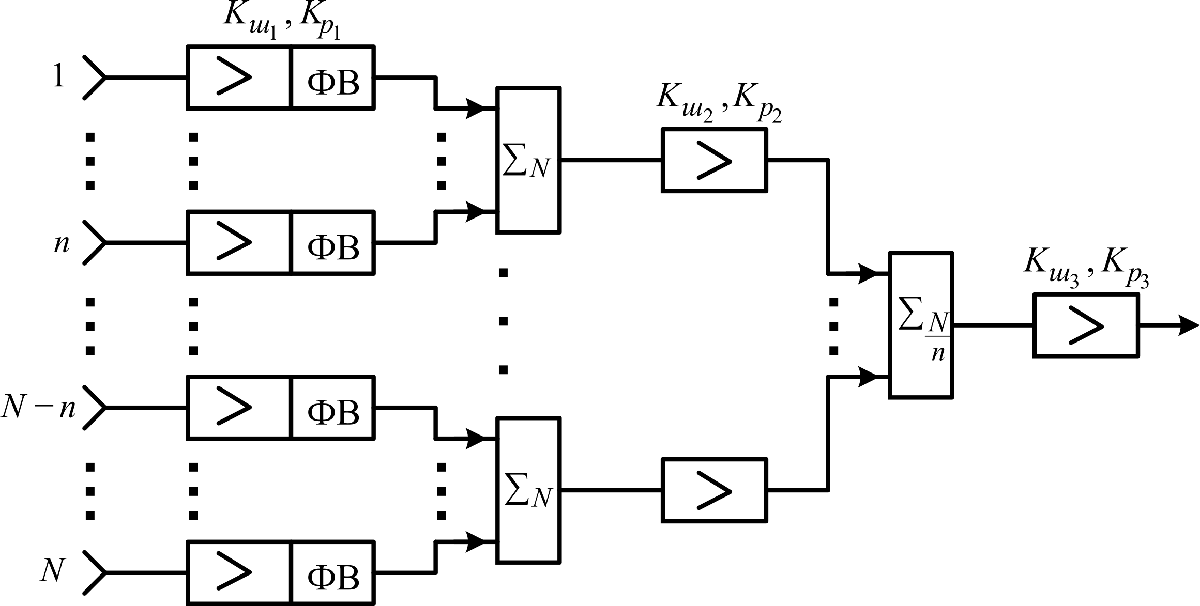

Возьмём потери в кабеле и фильтре МШУ $L_1=$

L1db=Lcab+0.2;
L1=db2pow(L1db);
fprintf(' = %.1f дБ = %.1f', L1db, L1)

 = 1.7 дБ = 1.5

Потери на ФВ $L_\text{ФВ}=6 \text{дБ}$ и в соединительных кабелях $L_\text{фид}= 1\text{ дБ}$, потери в сумматоре $L_{1\Sigma}=0.5 \text{ дБ}$ тогда $L_2=L_\text{ФВ}+L_\text{фид}+L_{1\Sigma}\cdot N_\text{э1}=$

L2db=1+Lps+0.5*3;
L2=db2pow(L2db);
fprintf(' = %.1f дБ = %.1f', L2db, L2)

 = 5.5 дБ = 3.5

Потери в соединительных кабелях $L_\text{фид}= 1\text{ дБ}$, потери в сумматоре $L_{1\Sigma}=0.5 \text{ дБ}$ тогда $L_3=L_\text{фид}+L_{1\Sigma}\cdot N_\text{э2}=$

L3db=1+0.5*5;
L3=db2pow(L3db);
fprintf(' = %.1f дБ = %.1f', L3db, L3)

 = 3.5 дБ = 2.2

Наконец $L_4=$

L4db=0.5;
L4=db2pow(L4db);
fprintf(' = %.1f дБ = %.1f', L4db, L4)

 = 0.5 дБ = 1.1


$$K_{\text{ш}_\Sigma}=K_\text{ш}L_1+\frac{(L_2-1)L_1}{K_p}+\frac{(K_\text{ш}-1)L_1L_2}{K_p}+\frac{(L_3-1)L_1L_2}{K^2_p}+\frac{(K_\text{ш}-1)L_1L_2L_3}{K^2_p}+\frac{(L_4-1)L_1L_2L_3}{K^2_p}+\frac{L_1L_2L_3L_4}{K^3_p}=$$


(опустим два последних слагаемых)

Knsum1=(L2-1)*L1/Kp;
Knsum2=(Kn-1)*L1*L2/Kp;
Knsum3=(L3-1)*L1*L2/Kp^2;
Knsum4=(Kn-1)*L1*L2*L3/Kp^2;
Knsum=Kn*L1+Knsum1+Knsum2+Knsum3+Knsum4;
fprintf(' = %.4f + %.4f + %.4f + %.4f + %.4f = %.2f', Kn*L1, Knsum1, Knsum2, Knsum3, Knsum4, Knsum)

 = 3.3103 + 0.0752 + 0.1297 + 0.0026 + 0.0058 = 3.52

Отношение остальных слагаемых к первому около

fprintf('%.1f %%',100*((Knsum1+Knsum2+Knsum3+Knsum4)/(Kn*L1)))

6.4 %

Проверим $\frac{L_\Sigma}{K_p}\leq 0.1\div0.5$ 


$$\frac{L_\Sigma}{K_p}=$$


fprintf('%.1f/%.0f = %.2f',L1+L2,Kp, (L2+L1)/Kp)

5.0/50 = 0.10

Необходимость перехода к 3этажной схеме отсутсвует.

Рассчитаем энергетический потенциал АФАР


$$\text{П}_\text{ПРМ}=\frac{S_\text{эфф}}{T_\text{эфф}}$$



$$S_\text{эфф}=A \cdot S_1 \cdot \sigma = A \cdot L \cdot W \cdot \sigma =$$


Seff=0.5*L*W*0.7;
fprintf('0.5*%.1f*%.1f*0.7 = %.0f',L,W,Seff)

0.5*211.9*211.9*0.7 = 15721


$$T_\text{эфф}=T_0\cdot(K_{\text{Ш}\Sigma}-1)=$$


Teff=290*(Knsum-1);
fprintf('290*(%.3f-1)=%.0f', Knsum, Teff)

290*(3.523-1)=732

Получаем $\text{П}_\text{ПРМ}=$

fprintf('%.0f/%.0f = %.2f (см^2/K)',Seff,Teff,Seff/Teff)

15721/732 = 21.48 (см^2/K)

## Точность выставки луча


$$\delta\theta=\frac{9\cdot\Delta\theta_{0.5}}{N\cdot2^p}$$


dThetaX=9*beamwidthx/(N1*2^p);
dThetaY=9*beamwidthy/(N2*2^p);
fprintf('dThetaX = %.2f dThetaY = %.2f',dThetaX,dThetaY)

dThetaX = 0.04 dThetaY = 0.04

##  Выбор излучателя

да спираль короче, бля буду

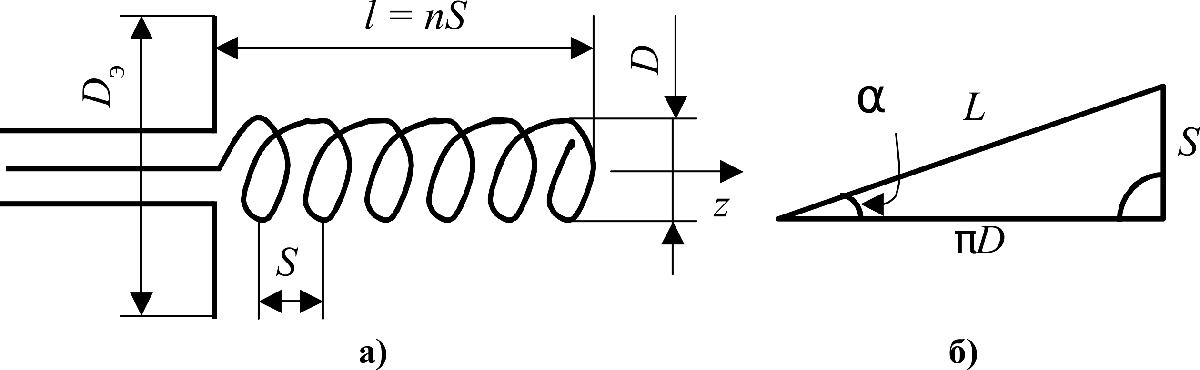


$$\Delta\theta_{0.5}=2\theta_\text{ск}=\frac{52^\circ\cdot\lambda}{L}\sqrt{\frac{\lambda}{l}}$$


$L=\lambda$ тогда $l=\frac{52^2\lambda}{4\theta^2_\text{ск}}=$

l=52^2*wavlen/4/scanang^2;
fprintf('%0.f*%0.f/(4*%0.f)=%.2f',52^2,wavlen,scanang^2,l)

2704*8/(4*484)=11.17

Шаг намотки: $S=L\cdot sin\alpha=8\cdot sin12^\circ=$

S=wavlen*sind(12);
fprintf('= %0.2f',S)

= 1.66

Диаметр намотки: $D=\frac{L\cdot cos\alpha}{\pi}=$

D=wavlen*cosd(12)/pi;
fprintf('= %0.2f',D)

= 2.49

Количество витков $n=l/S=$

n=l/S;
fprintf('= %0.2f',n)

= 6.72

Волновое сопротивление излучателя $Z_\text{вх}=\frac{140\cdot L}{\lambda}=140$ Ом